# `Dinámica de una partícula en un potencial de doble pozo`

`Modelado de Sistemas Dinámicos`

`Nombre: Sergio`

`Fecha: 24/04/2026`

## `Resumen`

`En este trabajo se analiza la dinámica de una partícula en un potencial de doble pozo. Se estudian los puntos de equilibrio y su estabilidad, se implementa el modelo en MATLAB y Simulink. Se realizan simulaciones numéricas mediante el método de Runge-Kutta de orden 4. Se obtiene que dado dos pozos, existe orbitas que no salen del pozo (baja energia) y orbitas que cambian de pozo (alta energía). Además, se descubre la influencia que tienen los parámetros a y b sobre la profundidad o amplitud de los pozos. Si aumenta b los pozos se hacen profundos y si aumenta a se hacen mas estrechos.`

## `Introducción`

`El presente experimento se enmarca en el estudio de sistemas dinámicos no lineales, centrándose en el análisis del movimiento de una partícula sometida a un potencial de doble pozo. Este tipo de sistemas constituye un caso clásico en física e ingeniería, ya que permite ilustrar fenómenos fundamentales como la existencia de múltiples puntos de equilibrio, la estabilidad de los mismos y la fuerte dependencia de la dinámica respecto a las condiciones iniciales y a los parámetros del sistema. Además, su comportamiento es representativo de numerosos sistemas reales, desde modelos mecánicos hasta procesos en física estadística y electrónica.`

`El problema abordado consiste en modelar, simular y analizar la evolución temporal del sistema, así como su representación en el espacio de fase, con el objetivo de comprender las trayectorias que describen sus estados y la estructura global de su dinámica. Para ello, se emplean herramientas de simulación numérica en MATLAB y Simulink, que permiten resolver la ecuación diferencial no lineal asociada y visualizar el comportamiento del sistema bajo distintas condiciones iniciales y configuraciones de parámetros.`

`La importancia de este estudio radica en la capacidad de los sistemas no lineales para presentar comportamientos complejos que no pueden inferirse directamente a partir de su ecuación, siendo necesario un análisis cualitativo y numérico. En particular, el sistema de doble pozo permite observar fenómenos como la existencia de regiones de atracción, trayectorias cerradas, separatrices y transiciones entre distintos regímenes dinámicos, aspectos clave en la teoría de sistemas dinámicos.`

`Los objetivos específicos del laboratorio son:`

- `Implementar el modelo del sistema en un entorno de simulación.`

- `Analizar su comportamiento dinámico mediante la representación en el espacio de fase.`

- `Estudiar la influencia de las condiciones iniciales en las trayectorias del sistema`

- `Evaluar el efecto de los parámetros del modelo sobre la forma del potencial y la dinámica resultante.`

`Con ello, se pretende adquirir una comprensión tanto teórica como práctica del comportamiento de sistemas dinámicos no lineales.`

## `Modelo matemático`

#### `Potencial`


$$V\left(x\right)=a*x^4 -b*x^2$$



$$\frac{\textrm{dV}}{\textrm{dx}}=4^* a*x^3 -2*b*x$$


#### ` Ecuación del movimiento`


$$m*x\prime \prime =\frac{\textrm{dV}}{\textrm{dx}}$$


#### ` Sistema de primer orden`


$$\begin{array}{l}
x_1 =x\\
x_2 =\frac{\textrm{dx}}{\textrm{dt}}\\
x_1 \prime =x_2 \\
x_2 \prime =-\left(\frac{4*a}{m}\right)*x^3 +\left(\frac{2*b}{m}\right)*x
\end{array}$$


#### `Puntos de equilibrio y estabilidad`


$$x*\left(4*a*x^2 -2*b\right)=0$$


`Las soluciones de la ecuacion de grado 3 anterior son:`


$$\begin{array}{l}
x=0\\
x=\pm \sqrt{\frac{b}{2*a}}
\end{array}$$


`Ahora es necesario evaluar estos puntos en la segunda derivada de la función V(x) para conocer si el punto es un maximo, minimo o punto de silla. En el caso de ser maximo, el punto es inestable, si es un minimo, el punto es estable y en el caso de ser un punto de silla, la estabilidad no es concluyente con solo esta información.`


$$\textrm{V"}\left(x\right)=12*a*x^2 -2*b$$


`Por tanto, teniendo en cuenta que los parametros a y b son constantes positivas, se obtiene que:`


$$\begin{array}{l}
\textrm{V"}\left(0\right)=-2b<0\\
V\left(\pm \sqrt{\frac{b}{2*a}}\right)=4b>0
\end{array}$$


`Por tanto, se deduce:`


$$\begin{array}{l}
x=0\to \textrm{inestable}\\
x=\pm \sqrt{\frac{b}{2*a}}\to \textrm{estables}
\end{array}$$


#### `Uso de Simulink y ejecución de la simulación`

`Para poder realizar las simulaciones en Simulink es necesario construir el modelo, es decir, el sistema de ecuaciones de primer orden:`


$$\begin{array}{l}
x_1 =x\\
x_2 =x^{\prime } \\
x_1^{\prime } =x_2 \\
x_2^{\prime } =\frac{-4*a}{m}*x_1^3 +\frac{2*b}{m}*x_1 
\end{array}$$


`En la herramienta de SimuLink se ha realizado el diagrama de control para la automatización del proceso y obtención de los datos para el modelo. A continuación se muestra una imagen del diagrama.`

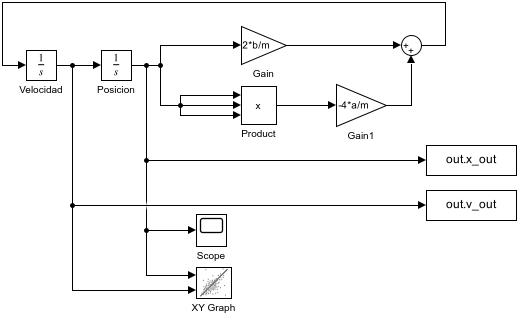

`Para la construcción del modelo en Simulink ha sido necesario adaptar la ecuación diferencial de segundo orden a una representación en variables de estado, lo que ha implicado el uso de dos bloques integradores en cascada para obtener la velocidad y la posición a partir de la aceleración. Las condiciones iniciales se han fijado directamente en estos integradores, estableciendo la posición inicial en x(0) = -1.5 y la velocidad inicial en cero.`

`La expresión de la aceleración se ha implementado mediante bloques matemáticos, utilizando un bloque Product para generar el término cúbico de la posición y bloques Gain para introducir los coeficientes del sistema, ajustados según los valores de los parámetros (a = 1/4 y b = 1/2), lo que resulta en ganancias de -1 y 1 respectivamente. Ambos términos se han combinado mediante un bloque Sum.`

`Además, se ha cerrado el lazo de realimentación conectando la salida de posición con los bloques que calculan la aceleración, dado que se trata de un sistema autónomo sin entradas externas. Finalmente, se ha configurado el solver de Simulink con un método de Runge-Kutta de orden 4 (ode4), un paso de integración de 0.01 y un intervalo de simulación de 0 a 100 segundos, asegurando así la correcta resolución numérica del sistema.`

`Con el diagrama ya realizado, es necesario incluir en el espacio de trabajo los valores indicados para las variables para a y b. Esto permite que la ejecucion de este sistema pueda varias segun las variables a y b. Despues se debe ejecutar la simulacion que nos permite obtener los valores de salida necesarios para realizar las graficas y sacar conclusiones.`

% Valores de las variables a y b
a=1/4
b=1/2
% Se toma m=1 como valor base en el caso de no indicarse
m=1
% Carga del modelo y simulacion para obtener los valores de salida
modelo = 'Actividad1_P1';
load_system(modelo)
simOut = sim(modelo);

`Habiendo ya ejecutado el modelo, es posible hacer uso en el espacio de trabajo de las variables de salida obtenidas y así poder crear los graficos deseados.`

t = simOut.x_out.time;
x = simOut.x_out.signals.values;
v = simOut.v_out.signals.values;

figure
subplot(2,1,1)
plot(t,x,'LineWidth',1.5)
title('Posición vs tiempo')
xlabel('t'); ylabel('x')
grid on

subplot(2,1,2)
plot(t,v,'LineWidth',1.5)
title('Velocidad vs tiempo')
xlabel('t'); ylabel('v')
grid on

figure
plot(x,v,'LineWidth',1.5)
title('Espacio de fase')
xlabel('x')
ylabel('v')
grid on

`En las graficas es posible observar diferentes resultados:`

- `En la grafica de posicion vs tiempo se puede observar las oscilaciones de la particula alrededor de un mínimo. La señal producida no es una funcion seno perfecta debido a que no es un sistema lineal y el potencial no es parabolico puro. La amplitud es aproximadamente constante y no decrece, lo que indica que es un sistema conservativo y no hay disipación. El periodo casi no varia, ya que depende de la amplitud en este caso.`

- `En la grafica de espacio de fase se puede ver que es una orbita cerrada lo que significa un movimiento periodico y energía constante. En este caso, la particula tiene suficiente energía para cruzar la barrera central, es decir, no se encuentra encerrada en un solo pozo sino que oscila entre ambos pozos.`

`A continuación se calcula la amplitud (A) y periodo de las oscilaciones (T).`

[pks, locs] = findpeaks(x,t);
A = max(abs(pks))
T = mean(diff(locs))

`A continuación se va a realizar las simulaciones variando las posiciones iniciales dentro del intervalo `$x_0 \in \left\lbrack -1\ldotp 5,1\ldotp 5\right\rbrack$`. Se van a tomar 20 condiciones iniciales dentro de este rango espaciadas de forma equidistante y se representa graficamente en el espacio de fase las orbitas.`

x0_vals = linspace(-1.5, 1.5, 20);
n = length(x0_vals);
modelo = 'Actividad1_P2';
load_system(modelo)
resultados = cell(n,1);
for i = 1:n
    x0 = x0_vals(i);
    simOut = sim(modelo);
    resultados{i}= simOut; % Guardamos simulación
end

% Representamos graficamente las orbitas en el espacio de fases
figure; hold on
for i = 1:n
    x = resultados{i}.x_out.signals.values;
    v = resultados{i}.v_out.signals.values;
    plot(x,v)
end
xlabel('x')
ylabel('v')
title('Espacio de fases')
grid on

`Viendo la grafica del espacio de fases se pueden observar diferentes caracteristicas del sistema:`

- `Se pueden observar dos regiones cerradas definidas sobre `$x=1$` y `$x=-1$`. Esto significa que son dos puntos de equilibrio estables.`

- `En la zona central, alrededor de `$x=0$` se observa que las trayectorias se estrechan y algunas pasan de un lado al otro. Esto significa que es un punto de equilibrio inestable. Es un punto de silla.`

- `Se observan tres tipos de trayectorias en el espacio de fases. En primer lugar estan las orbitas internas cerradas (dentro de cada pozo), se encuentran centradas sobre los puntos de equilibrio estables y su energia es baja. En segundo lugar estan las orbitas externas, son de gran tamaño, rodean todo el sistema y son de energia alta. Por ultimo esta la trayectoria critica, es la energia exacta necesaria para escapar del pozo. Esta trayectoria se llama separatriz.`

`A continuación se va a estudiar la dinámica del sistema variando los parametros a y b de los pozos para poder analizar la forma y profundidad de estos.`

a_vals = [0.1 0.25 0.5];
na = length(a_vals);
b_vals = [0.2 0.5 1];
nb = length(b_vals);
resultados = cell(na, nb);

% Simulamos cada una de las trayectorias y guardamos los valores obtenidos
for ia = 1:na
    for ib = 1:nb

        a = a_vals(ia);
        b = b_vals(ib);

        trayectorias = cell(n,1);

        for i = 1:n

            x0 = x0_vals(i);

            simOut = sim(modelo);

            x = simOut.x_out.signals.values;
            v = simOut.v_out.signals.values;

            trayectorias{i} = [x, v];
        end

        resultados{ia,ib} = trayectorias;
    end
end

% Se representan graficamente las simulaciones con diferentes valores para
% los parametros a y b
for ia = 1:na
    for ib = 1:nb
        figure; hold on

        tray = resultados{ia,ib};

        for i = 1:length(tray)
            data = tray{i};
            plot(data(:,1), data(:,2))
        end

        title(sprintf('a=%.2f, b=%.2f', a_vals(ia), b_vals(ib)))
        xlabel('x'); ylabel('v'); grid on
    end
end